# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       ex1.mlx                 featureNormalize.m      lib                     token.mat               
..                      ex1_companion.mlx       gradientDescent.asv     normalEqn.m             warmUpExercise.m        
computeCost.m           ex1data1.txt            gradientDescent.m       plotData.m              
computeCostMulti.m      ex1data2.txt            gradientDescentMulti.m  submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

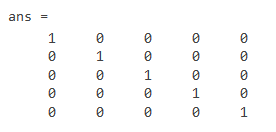

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

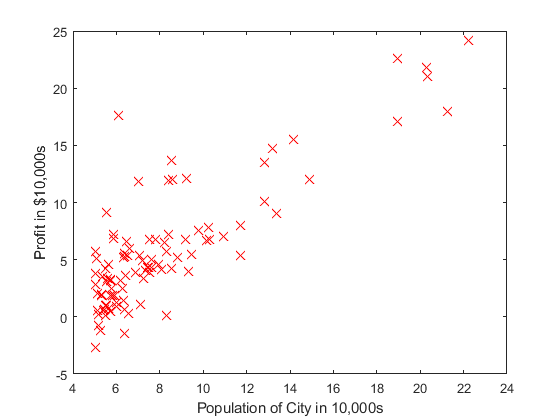

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

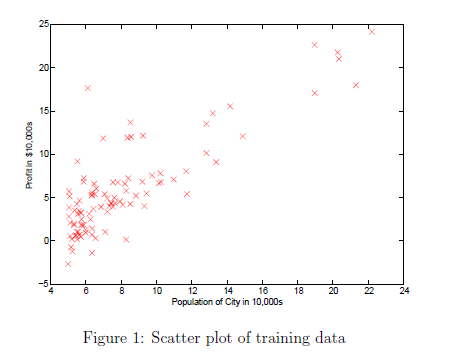

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\mathrm{simultaneously}\;\mathrm{update}\;\theta_{j\;} \;\mathrm{for}\;\mathrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

J = 32.0727

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

J = 54.2425

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

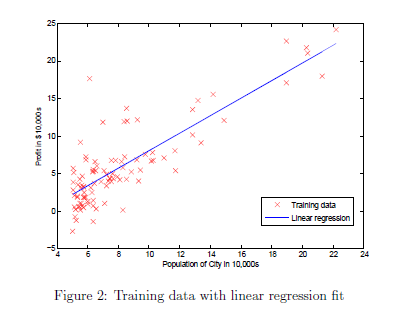    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

J = 6.7372

J = 5.9316

J = 5.9012

J = 5.8952

J = 5.8901

J = 5.8850

J = 5.8799

J = 5.8749

J = 5.8698

J = 5.8648

J = 5.8598

J = 5.8548

J = 5.8499

J = 5.8449

J = 5.8400

J = 5.8351

J = 5.8302

J = 5.8253

J = 5.8205

J = 5.8156

J = 5.8108

J = 5.8060

J = 5.8012

J = 5.7965

J = 5.7917

J = 5.7870

J = 5.7822

J = 5.7775

J = 5.7729

J = 5.7682

J = 5.7635

J = 5.7589

J = 5.7543

J = 5.7497

J = 5.7451

J = 5.7405

J = 5.7360

J = 5.7315

J = 5.7269

J = 5.7224

J = 5.7179

J = 5.7135

J = 5.7090

J = 5.7046

J = 5.7002

J = 5.6958

J = 5.6914

J = 5.6870

J = 5.6826

J = 5.6783

J = 5.6740

J = 5.6697

J = 5.6654

J = 5.6611

J = 5.6568

J = 5.6526

J = 5.6483

J = 5.6441

J = 5.6399

J = 5.6357

J = 5.6315

J = 5.6274

J = 5.6232

J = 5.6191

J = 5.6150

J = 5.6109

J = 5.6068

J = 5.6027

J = 5.5987

J = 5.5946

J = 5.5906

J = 5.5866

J = 5.5826

J = 5.5786

J = 5.5747

J = 5.5707

J = 5.5668

J = 5.5628

J = 5.5589

J = 5.5550

J = 5.5512

J = 5.5473

J = 5.5434

J = 5.5396

J = 5.5358

J = 5.5319

J = 5.5281

J = 5.5244

J = 5.5206

J = 5.5168

J = 5.5131

J = 5.5094

J = 5.5056

J = 5.5019

J = 5.4982

J = 5.4946

J = 5.4909

J = 5.4872

J = 5.4836

J = 5.4800

J = 5.4764

J = 5.4728

J = 5.4692

J = 5.4656

J = 5.4620

J = 5.4585

J = 5.4550

J = 5.4514

J = 5.4479

J = 5.4444

J = 5.4409

J = 5.4375

J = 5.4340

J = 5.4306

J = 5.4271

J = 5.4237

J = 5.4203

J = 5.4169

J = 5.4135

J = 5.4101

J = 5.4068

J = 5.4034

J = 5.4001

J = 5.3968

J = 5.3935

J = 5.3902

J = 5.3869

J = 5.3836

J = 5.3803

J = 5.3771

J = 5.3738

J = 5.3706

J = 5.3674

J = 5.3642

J = 5.3610

J = 5.3578

J = 5.3546

J = 5.3515

J = 5.3483

J = 5.3452

J = 5.3420

J = 5.3389

J = 5.3358

J = 5.3327

J = 5.3296

J = 5.3266

J = 5.3235

J = 5.3205

J = 5.3174

J = 5.3144

J = 5.3114

J = 5.3084

J = 5.3054

J = 5.3024

J = 5.2994

J = 5.2965

J = 5.2935

J = 5.2906

J = 5.2876

J = 5.2847

J = 5.2818

J = 5.2789

J = 5.2760

J = 5.2731

J = 5.2703

J = 5.2674

J = 5.2646

J = 5.2617

J = 5.2589

J = 5.2561

J = 5.2533

J = 5.2505

J = 5.2477

J = 5.2449

J = 5.2422

J = 5.2394

J = 5.2367

J = 5.2339

J = 5.2312

J = 5.2285

J = 5.2258

J = 5.2231

J = 5.2204

J = 5.2177

J = 5.2150

J = 5.2124

J = 5.2097

J = 5.2071

J = 5.2045

J = 5.2018

J = 5.1992

J = 5.1966

J = 5.1940

J = 5.1915

J = 5.1889

J = 5.1863

J = 5.1838

J = 5.1812

J = 5.1787

J = 5.1762

J = 5.1736

J = 5.1711

J = 5.1686

J = 5.1661

J = 5.1637

J = 5.1612

J = 5.1587

J = 5.1563

J = 5.1538

J = 5.1514

J = 5.1489

J = 5.1465

J = 5.1441

J = 5.1417

J = 5.1393

J = 5.1369

J = 5.1346

J = 5.1322

J = 5.1298

J = 5.1275

J = 5.1251

J = 5.1228

J = 5.1205

J = 5.1181

J = 5.1158

J = 5.1135

J = 5.1112

J = 5.1090

J = 5.1067

J = 5.1044

J = 5.1022

J = 5.0999

J = 5.0977

J = 5.0954

J = 5.0932

J = 5.0910

J = 5.0888

J = 5.0866

J = 5.0844

J = 5.0822

J = 5.0800

J = 5.0778

J = 5.0757

J = 5.0735

J = 5.0714

J = 5.0692

J = 5.0671

J = 5.0650

J = 5.0628

J = 5.0607

J = 5.0586

J = 5.0565

J = 5.0544

J = 5.0524

J = 5.0503

J = 5.0482

J = 5.0462

J = 5.0441

J = 5.0421

J = 5.0400

J = 5.0380

J = 5.0360

J = 5.0340

J = 5.0320

J = 5.0300

J = 5.0280

J = 5.0260

J = 5.0240

J = 5.0220

J = 5.0201

J = 5.0181

J = 5.0162

J = 5.0142

J = 5.0123

J = 5.0104

J = 5.0085

J = 5.0065

J = 5.0046

J = 5.0027

J = 5.0008

J = 4.9989

J = 4.9971

J = 4.9952

J = 4.9933

J = 4.9915

J = 4.9896

J = 4.9878

J = 4.9859

J = 4.9841

J = 4.9823

J = 4.9805

J = 4.9786

J = 4.9768

J = 4.9750

J = 4.9732

J = 4.9714

J = 4.9697

J = 4.9679

J = 4.9661

J = 4.9644

J = 4.9626

J = 4.9609

J = 4.9591

J = 4.9574

J = 4.9556

J = 4.9539

J = 4.9522

J = 4.9505

J = 4.9488

J = 4.9471

J = 4.9454

J = 4.9437

J = 4.9420

J = 4.9404

J = 4.9387

J = 4.9370

J = 4.9354

J = 4.9337

J = 4.9321

J = 4.9304

J = 4.9288

J = 4.9272

J = 4.9255

J = 4.9239

J = 4.9223

J = 4.9207

J = 4.9191

J = 4.9175

J = 4.9159

J = 4.9144

J = 4.9128

J = 4.9112

J = 4.9096

J = 4.9081

J = 4.9065

J = 4.9050

J = 4.9034

J = 4.9019

J = 4.9004

J = 4.8989

J = 4.8973

J = 4.8958

J = 4.8943

J = 4.8928

J = 4.8913

J = 4.8898

J = 4.8883

J = 4.8868

J = 4.8854

J = 4.8839

J = 4.8824

J = 4.8810

J = 4.8795

J = 4.8781

J = 4.8766

J = 4.8752

J = 4.8738

J = 4.8723

J = 4.8709

J = 4.8695

J = 4.8681

J = 4.8667

J = 4.8653

J = 4.8639

J = 4.8625

J = 4.8611

J = 4.8597

J = 4.8583

J = 4.8569

J = 4.8556

J = 4.8542

J = 4.8528

J = 4.8515

J = 4.8501

J = 4.8488

J = 4.8475

J = 4.8461

J = 4.8448

J = 4.8435

J = 4.8422

J = 4.8408

J = 4.8395

J = 4.8382

J = 4.8369

J = 4.8356

J = 4.8343

J = 4.8330

J = 4.8318

J = 4.8305

J = 4.8292

J = 4.8279

J = 4.8267

J = 4.8254

J = 4.8242

J = 4.8229

J = 4.8217

J = 4.8204

J = 4.8192

J = 4.8180

J = 4.8167

J = 4.8155

J = 4.8143

J = 4.8131

J = 4.8119

J = 4.8107

J = 4.8094

J = 4.8083

J = 4.8071

J = 4.8059

J = 4.8047

J = 4.8035

J = 4.8023

J = 4.8012

J = 4.8000

J = 4.7988

J = 4.7977

J = 4.7965

J = 4.7954

J = 4.7942

J = 4.7931

J = 4.7919

J = 4.7908

J = 4.7897

J = 4.7885

J = 4.7874

J = 4.7863

J = 4.7852

J = 4.7841

J = 4.7830

J = 4.7819

J = 4.7808

J = 4.7797

J = 4.7786

J = 4.7775

J = 4.7764

J = 4.7753

J = 4.7743

J = 4.7732

J = 4.7721

J = 4.7711

J = 4.7700

J = 4.7689

J = 4.7679

J = 4.7668

J = 4.7658

J = 4.7648

J = 4.7637

J = 4.7627

J = 4.7617

J = 4.7606

J = 4.7596

J = 4.7586

J = 4.7576

J = 4.7566

J = 4.7556

J = 4.7546

J = 4.7536

J = 4.7526

J = 4.7516

J = 4.7506

J = 4.7496

J = 4.7486

J = 4.7476

J = 4.7467

J = 4.7457

J = 4.7447

J = 4.7438

J = 4.7428

J = 4.7418

J = 4.7409

J = 4.7399

J = 4.7390

J = 4.7380

J = 4.7371

J = 4.7362

J = 4.7352

J = 4.7343

J = 4.7334

J = 4.7325

J = 4.7315

J = 4.7306

J = 4.7297

J = 4.7288

J = 4.7279

J = 4.7270

J = 4.7261

J = 4.7252

J = 4.7243

J = 4.7234

J = 4.7225

J = 4.7216

J = 4.7207

J = 4.7199

J = 4.7190

J = 4.7181

J = 4.7173

J = 4.7164

J = 4.7155

J = 4.7147

J = 4.7138

J = 4.7130

J = 4.7121

J = 4.7113

J = 4.7104

J = 4.7096

J = 4.7087

J = 4.7079

J = 4.7071

J = 4.7062

J = 4.7054

J = 4.7046

J = 4.7038

J = 4.7030

J = 4.7021

J = 4.7013

J = 4.7005

J = 4.6997

J = 4.6989

J = 4.6981

J = 4.6973

J = 4.6965

J = 4.6957

J = 4.6949

J = 4.6942

J = 4.6934

J = 4.6926

J = 4.6918

J = 4.6910

J = 4.6903

J = 4.6895

J = 4.6887

J = 4.6880

J = 4.6872

J = 4.6865

J = 4.6857

J = 4.6850

J = 4.6842

J = 4.6835

J = 4.6827

J = 4.6820

J = 4.6812

J = 4.6805

J = 4.6798

J = 4.6790

J = 4.6783

J = 4.6776

J = 4.6769

J = 4.6761

J = 4.6754

J = 4.6747

J = 4.6740

J = 4.6733

J = 4.6726

J = 4.6719

J = 4.6712

J = 4.6705

J = 4.6698

J = 4.6691

J = 4.6684

J = 4.6677

J = 4.6670

J = 4.6663

J = 4.6656

J = 4.6650

J = 4.6643

J = 4.6636

J = 4.6629

J = 4.6623

J = 4.6616

J = 4.6609

J = 4.6603

J = 4.6596

J = 4.6590

J = 4.6583

J = 4.6577

J = 4.6570

J = 4.6564

J = 4.6557

J = 4.6551

J = 4.6544

J = 4.6538

J = 4.6531

J = 4.6525

J = 4.6519

J = 4.6513

J = 4.6506

J = 4.6500

J = 4.6494

J = 4.6488

J = 4.6481

J = 4.6475

J = 4.6469

J = 4.6463

J = 4.6457

J = 4.6451

J = 4.6445

J = 4.6439

J = 4.6433

J = 4.6427

J = 4.6421

J = 4.6415

J = 4.6409

J = 4.6403

J = 4.6397

J = 4.6391

J = 4.6385

J = 4.6380

J = 4.6374

J = 4.6368

J = 4.6362

J = 4.6356

J = 4.6351

J = 4.6345

J = 4.6339

J = 4.6334

J = 4.6328

J = 4.6322

J = 4.6317

J = 4.6311

J = 4.6306

J = 4.6300

J = 4.6295

J = 4.6289

J = 4.6284

J = 4.6278

J = 4.6273

J = 4.6267

J = 4.6262

J = 4.6257

J = 4.6251

J = 4.6246

J = 4.6241

J = 4.6235

J = 4.6230

J = 4.6225

J = 4.6220

J = 4.6214

J = 4.6209

J = 4.6204

J = 4.6199

J = 4.6194

J = 4.6189

J = 4.6183

J = 4.6178

J = 4.6173

J = 4.6168

J = 4.6163

J = 4.6158

J = 4.6153

J = 4.6148

J = 4.6143

J = 4.6138

J = 4.6133

J = 4.6128

J = 4.6123

J = 4.6119

J = 4.6114

J = 4.6109

J = 4.6104

J = 4.6099

J = 4.6094

J = 4.6090

J = 4.6085

J = 4.6080

J = 4.6076

J = 4.6071

J = 4.6066

J = 4.6061

J = 4.6057

J = 4.6052

J = 4.6048

J = 4.6043

J = 4.6038

J = 4.6034

J = 4.6029

J = 4.6025

J = 4.6020

J = 4.6016

J = 4.6011

J = 4.6007

J = 4.6002

J = 4.5998

J = 4.5993

J = 4.5989

J = 4.5985

J = 4.5980

J = 4.5976

J = 4.5972

J = 4.5967

J = 4.5963

J = 4.5959

J = 4.5954

J = 4.5950

J = 4.5946

J = 4.5942

J = 4.5937

J = 4.5933

J = 4.5929

J = 4.5925

J = 4.5921

J = 4.5916

J = 4.5912

J = 4.5908

J = 4.5904

J = 4.5900

J = 4.5896

J = 4.5892

J = 4.5888

J = 4.5884

J = 4.5880

J = 4.5876

J = 4.5872

J = 4.5868

J = 4.5864

J = 4.5860

J = 4.5856

J = 4.5852

J = 4.5848

J = 4.5844

J = 4.5840

J = 4.5837

J = 4.5833

J = 4.5829

J = 4.5825

J = 4.5821

J = 4.5818

J = 4.5814

J = 4.5810

J = 4.5806

J = 4.5803

J = 4.5799

J = 4.5795

J = 4.5791

J = 4.5788

J = 4.5784

J = 4.5780

J = 4.5777

J = 4.5773

J = 4.5770

J = 4.5766

J = 4.5762

J = 4.5759

J = 4.5755

J = 4.5752

J = 4.5748

J = 4.5745

J = 4.5741

J = 4.5738

J = 4.5734

J = 4.5731

J = 4.5727

J = 4.5724

J = 4.5720

J = 4.5717

J = 4.5713

J = 4.5710

J = 4.5707

J = 4.5703

J = 4.5700

J = 4.5697

J = 4.5693

J = 4.5690

J = 4.5687

J = 4.5683

J = 4.5680

J = 4.5677

J = 4.5673

J = 4.5670

J = 4.5667

J = 4.5664

J = 4.5660

J = 4.5657

J = 4.5654

J = 4.5651

J = 4.5648

J = 4.5645

J = 4.5641

J = 4.5638

J = 4.5635

J = 4.5632

J = 4.5629

J = 4.5626

J = 4.5623

J = 4.5620

J = 4.5617

J = 4.5614

J = 4.5611

J = 4.5607

J = 4.5604

J = 4.5601

J = 4.5598

J = 4.5595

J = 4.5592

J = 4.5590

J = 4.5587

J = 4.5584

J = 4.5581

J = 4.5578

J = 4.5575

J = 4.5572

J = 4.5569

J = 4.5566

J = 4.5563

J = 4.5560

J = 4.5558

J = 4.5555

J = 4.5552

J = 4.5549

J = 4.5546

J = 4.5544

J = 4.5541

J = 4.5538

J = 4.5535

J = 4.5532

J = 4.5530

J = 4.5527

J = 4.5524

J = 4.5522

J = 4.5519

J = 4.5516

J = 4.5513

J = 4.5511

J = 4.5508

J = 4.5505

J = 4.5503

J = 4.5500

J = 4.5497

J = 4.5495

J = 4.5492

J = 4.5490

J = 4.5487

J = 4.5484

J = 4.5482

J = 4.5479

J = 4.5477

J = 4.5474

J = 4.5472

J = 4.5469

J = 4.5467

J = 4.5464

J = 4.5462

J = 4.5459

J = 4.5457

J = 4.5454

J = 4.5452

J = 4.5449

J = 4.5447

J = 4.5444

J = 4.5442

J = 4.5440

J = 4.5437

J = 4.5435

J = 4.5432

J = 4.5430

J = 4.5428

J = 4.5425

J = 4.5423

J = 4.5420

J = 4.5418

J = 4.5416

J = 4.5413

J = 4.5411

J = 4.5409

J = 4.5407

J = 4.5404

J = 4.5402

J = 4.5400

J = 4.5397

J = 4.5395

J = 4.5393

J = 4.5391

J = 4.5388

J = 4.5386

J = 4.5384

J = 4.5382

J = 4.5380

J = 4.5377

J = 4.5375

J = 4.5373

J = 4.5371

J = 4.5369

J = 4.5366

J = 4.5364

J = 4.5362

J = 4.5360

J = 4.5358

J = 4.5356

J = 4.5354

J = 4.5352

J = 4.5350

J = 4.5347

J = 4.5345

J = 4.5343

J = 4.5341

J = 4.5339

J = 4.5337

J = 4.5335

J = 4.5333

J = 4.5331

J = 4.5329

J = 4.5327

J = 4.5325

J = 4.5323

J = 4.5321

J = 4.5319

J = 4.5317

J = 4.5315

J = 4.5313

J = 4.5311

J = 4.5309

J = 4.5307

J = 4.5305

J = 4.5303

J = 4.5301

J = 4.5299

J = 4.5298

J = 4.5296

J = 4.5294

J = 4.5292

J = 4.5290

J = 4.5288

J = 4.5286

J = 4.5284

J = 4.5283

J = 4.5281

J = 4.5279

J = 4.5277

J = 4.5275

J = 4.5273

J = 4.5272

J = 4.5270

J = 4.5268

J = 4.5266

J = 4.5264

J = 4.5263

J = 4.5261

J = 4.5259

J = 4.5257

J = 4.5256

J = 4.5254

J = 4.5252

J = 4.5250

J = 4.5249

J = 4.5247

J = 4.5245

J = 4.5243

J = 4.5242

J = 4.5240

J = 4.5238

J = 4.5237

J = 4.5235

J = 4.5233

J = 4.5232

J = 4.5230

J = 4.5228

J = 4.5227

J = 4.5225

J = 4.5223

J = 4.5222

J = 4.5220

J = 4.5218

J = 4.5217

J = 4.5215

J = 4.5214

J = 4.5212

J = 4.5210

J = 4.5209

J = 4.5207

J = 4.5206

J = 4.5204

J = 4.5203

J = 4.5201

J = 4.5199

J = 4.5198

J = 4.5196

J = 4.5195

J = 4.5193

J = 4.5192

J = 4.5190

J = 4.5189

J = 4.5187

J = 4.5186

J = 4.5184

J = 4.5183

J = 4.5181

J = 4.5180

J = 4.5178

J = 4.5177

J = 4.5175

J = 4.5174

J = 4.5172

J = 4.5171

J = 4.5170

J = 4.5168

J = 4.5167

J = 4.5165

J = 4.5164

J = 4.5162

J = 4.5161

J = 4.5160

J = 4.5158

J = 4.5157

J = 4.5155

J = 4.5154

J = 4.5153

J = 4.5151

J = 4.5150

J = 4.5148

J = 4.5147

J = 4.5146

J = 4.5144

J = 4.5143

J = 4.5142

J = 4.5140

J = 4.5139

J = 4.5138

J = 4.5136

J = 4.5135

J = 4.5134

J = 4.5132

J = 4.5131

J = 4.5130

J = 4.5129

J = 4.5127

J = 4.5126

J = 4.5125

J = 4.5123

J = 4.5122

J = 4.5121

J = 4.5120

J = 4.5118

J = 4.5117

J = 4.5116

J = 4.5115

J = 4.5113

J = 4.5112

J = 4.5111

J = 4.5110

J = 4.5108

J = 4.5107

J = 4.5106

J = 4.5105

J = 4.5104

J = 4.5102

J = 4.5101

J = 4.5100

J = 4.5099

J = 4.5098

J = 4.5096

J = 4.5095

J = 4.5094

J = 4.5093

J = 4.5092

J = 4.5091

J = 4.5089

J = 4.5088

J = 4.5087

J = 4.5086

J = 4.5085

J = 4.5084

J = 4.5083

J = 4.5081

J = 4.5080

J = 4.5079

J = 4.5078

J = 4.5077

J = 4.5076

J = 4.5075

J = 4.5074

J = 4.5073

J = 4.5071

J = 4.5070

J = 4.5069

J = 4.5068

J = 4.5067

J = 4.5066

J = 4.5065

J = 4.5064

J = 4.5063

J = 4.5062

J = 4.5061

J = 4.5060

J = 4.5059

J = 4.5058

J = 4.5057

J = 4.5056

J = 4.5055

J = 4.5053

J = 4.5052

J = 4.5051

J = 4.5050

J = 4.5049

J = 4.5048

J = 4.5047

J = 4.5046

J = 4.5045

J = 4.5044

J = 4.5043

J = 4.5042

J = 4.5041

J = 4.5040

J = 4.5040

J = 4.5039

J = 4.5038

J = 4.5037

J = 4.5036

J = 4.5035

J = 4.5034

J = 4.5033

J = 4.5032

J = 4.5031

J = 4.5030

J = 4.5029

J = 4.5028

J = 4.5027

J = 4.5026

J = 4.5025

J = 4.5024

J = 4.5023

J = 4.5023

J = 4.5022

J = 4.5021

J = 4.5020

J = 4.5019

J = 4.5018

J = 4.5017

J = 4.5016

J = 4.5015

J = 4.5014

J = 4.5014

J = 4.5013

J = 4.5012

J = 4.5011

J = 4.5010

J = 4.5009

J = 4.5008

J = 4.5008

J = 4.5007

J = 4.5006

J = 4.5005

J = 4.5004

J = 4.5003

J = 4.5002

J = 4.5002

J = 4.5001

J = 4.5000

J = 4.4999

J = 4.4998

J = 4.4997

J = 4.4997

J = 4.4996

J = 4.4995

J = 4.4994

J = 4.4993

J = 4.4993

J = 4.4992

J = 4.4991

J = 4.4990

J = 4.4989

J = 4.4989

J = 4.4988

J = 4.4987

J = 4.4986

J = 4.4985

J = 4.4985

J = 4.4984

J = 4.4983

J = 4.4982

J = 4.4982

J = 4.4981

J = 4.4980

J = 4.4979

J = 4.4979

J = 4.4978

J = 4.4977

J = 4.4976

J = 4.4976

J = 4.4975

J = 4.4974

J = 4.4973

J = 4.4973

J = 4.4972

J = 4.4971

J = 4.4970

J = 4.4970

J = 4.4969

J = 4.4968

J = 4.4968

J = 4.4967

J = 4.4966

J = 4.4965

J = 4.4965

J = 4.4964

J = 4.4963

J = 4.4963

J = 4.4962

J = 4.4961

J = 4.4961

J = 4.4960

J = 4.4959

J = 4.4958

J = 4.4958

J = 4.4957

J = 4.4956

J = 4.4956

J = 4.4955

J = 4.4954

J = 4.4954

J = 4.4953

J = 4.4952

J = 4.4952

J = 4.4951

J = 4.4950

J = 4.4950

J = 4.4949

J = 4.4949

J = 4.4948

J = 4.4947

J = 4.4947

J = 4.4946

J = 4.4945

J = 4.4945

J = 4.4944

J = 4.4943

J = 4.4943

J = 4.4942

J = 4.4942

J = 4.4941

J = 4.4940

J = 4.4940

J = 4.4939

J = 4.4938

J = 4.4938

J = 4.4937

J = 4.4937

J = 4.4936

J = 4.4935

J = 4.4935

J = 4.4934

J = 4.4934

J = 4.4933

J = 4.4933

J = 4.4932

J = 4.4931

J = 4.4931

J = 4.4930

J = 4.4930

J = 4.4929

J = 4.4928

J = 4.4928

J = 4.4927

J = 4.4927

J = 4.4926

J = 4.4926

J = 4.4925

J = 4.4924

J = 4.4924

J = 4.4923

J = 4.4923

J = 4.4922

J = 4.4922

J = 4.4921

J = 4.4921

J = 4.4920

J = 4.4920

J = 4.4919

J = 4.4918

J = 4.4918

J = 4.4917

J = 4.4917

J = 4.4916

J = 4.4916

J = 4.4915

J = 4.4915

J = 4.4914

J = 4.4914

J = 4.4913

J = 4.4913

J = 4.4912

J = 4.4912

J = 4.4911

J = 4.4911

J = 4.4910

J = 4.4910

J = 4.4909

J = 4.4909

J = 4.4908

J = 4.4908

J = 4.4907

J = 4.4907

J = 4.4906

J = 4.4906

J = 4.4905

J = 4.4905

J = 4.4904

J = 4.4904

J = 4.4903

J = 4.4903

J = 4.4902

J = 4.4902

J = 4.4901

J = 4.4901

J = 4.4900

J = 4.4900

J = 4.4899

J = 4.4899

J = 4.4898

J = 4.4898

J = 4.4898

J = 4.4897

J = 4.4897

J = 4.4896

J = 4.4896

J = 4.4895

J = 4.4895

J = 4.4894

J = 4.4894

J = 4.4893

J = 4.4893

J = 4.4893

J = 4.4892

J = 4.4892

J = 4.4891

J = 4.4891

J = 4.4890

J = 4.4890

J = 4.4890

J = 4.4889

J = 4.4889

J = 4.4888

J = 4.4888

J = 4.4887

J = 4.4887

J = 4.4887

J = 4.4886

J = 4.4886

J = 4.4885

J = 4.4885

J = 4.4884

J = 4.4884

J = 4.4884

J = 4.4883

J = 4.4883

J = 4.4882

J = 4.4882

J = 4.4882

J = 4.4881

J = 4.4881

J = 4.4880

J = 4.4880

J = 4.4880

J = 4.4879

J = 4.4879

J = 4.4878

J = 4.4878

J = 4.4878

J = 4.4877

J = 4.4877

J = 4.4876

J = 4.4876

J = 4.4876

J = 4.4875

J = 4.4875

J = 4.4875

J = 4.4874

J = 4.4874

J = 4.4873

J = 4.4873

J = 4.4873

J = 4.4872

J = 4.4872

J = 4.4872

J = 4.4871

J = 4.4871

J = 4.4870

J = 4.4870

J = 4.4870

J = 4.4869

J = 4.4869

J = 4.4869

J = 4.4868

J = 4.4868

J = 4.4868

J = 4.4867

J = 4.4867

J = 4.4867

J = 4.4866

J = 4.4866

J = 4.4865

J = 4.4865

J = 4.4865

J = 4.4864

J = 4.4864

J = 4.4864

J = 4.4863

J = 4.4863

J = 4.4863

J = 4.4862

J = 4.4862

J = 4.4862

J = 4.4861

J = 4.4861

J = 4.4861

J = 4.4860

J = 4.4860

J = 4.4860

J = 4.4859

J = 4.4859

J = 4.4859

J = 4.4859

J = 4.4858

J = 4.4858

J = 4.4858

J = 4.4857

J = 4.4857

J = 4.4857

J = 4.4856

J = 4.4856

J = 4.4856

J = 4.4855

J = 4.4855

J = 4.4855

J = 4.4854

J = 4.4854

J = 4.4854

J = 4.4854

J = 4.4853

J = 4.4853

J = 4.4853

J = 4.4852

J = 4.4852

J = 4.4852

J = 4.4851

J = 4.4851

J = 4.4851

J = 4.4851

J = 4.4850

J = 4.4850

J = 4.4850

J = 4.4849

J = 4.4849

J = 4.4849

J = 4.4849

J = 4.4848

J = 4.4848

J = 4.4848

J = 4.4847

J = 4.4847

J = 4.4847

J = 4.4847

J = 4.4846

J = 4.4846

J = 4.4846

J = 4.4845

J = 4.4845

J = 4.4845

J = 4.4845

J = 4.4844

J = 4.4844

J = 4.4844

J = 4.4844

J = 4.4843

J = 4.4843

J = 4.4843

J = 4.4843

J = 4.4842

J = 4.4842

J = 4.4842

J = 4.4841

J = 4.4841

J = 4.4841

J = 4.4841

J = 4.4840

J = 4.4840

J = 4.4840

J = 4.4840

J = 4.4839

J = 4.4839

J = 4.4839

J = 4.4839

J = 4.4838

J = 4.4838

J = 4.4838

J = 4.4838

J = 4.4837

J = 4.4837

J = 4.4837

J = 4.4837

J = 4.4836

J = 4.4836

J = 4.4836

J = 4.4836

J = 4.4836

J = 4.4835

J = 4.4835

J = 4.4835

J = 4.4835

J = 4.4834

J = 4.4834

J = 4.4834


% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

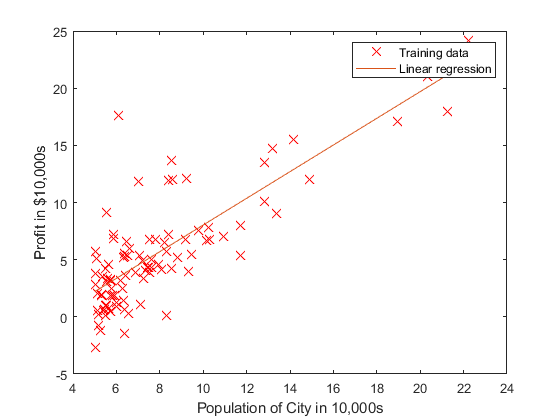


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

J = 328.0929

J = 316.6649

J = 305.4445

J = 294.4317

J = 283.6266

J = 273.0291

J = 262.6393

J = 252.4571

J = 242.4826

J = 232.7157

J = 223.1564

J = 213.8048

J = 204.6608

J = 195.7245

J = 186.9958

J = 178.4747

J = 170.1613

J = 162.0556

J = 154.1575

J = 146.4670

J = 138.9841

J = 131.7089

J = 124.6414

J = 117.7815

J = 111.1292

J = 104.6846

J = 98.4476

J = 92.4182

J = 86.5965

J = 80.9824

J = 75.5760

J = 70.3772

J = 65.3861

J = 60.6026

J = 56.0268

J = 51.6586

J = 47.4980

J = 43.5451

J = 39.7998

J = 36.2621

J = 32.9321

J = 29.8098

J = 26.8950

J = 24.1880

J = 21.6885

J = 19.3967

J = 17.3126

J = 15.4361

J = 13.7672

J = 12.3060

J = 11.0524

J = 10.0065

J = 9.1682

J = 8.5375

J = 8.1145

J = 7.8991

J = 7.8914

J = 8.0913

J = 8.4989

J = 9.1141

J = 9.9369

J = 10.9674

J = 12.2055

J = 13.6513

J = 15.3047

J = 17.1657

J = 19.2344

J = 21.5107

J = 23.9947

J = 26.6863

J = 29.5856

J = 32.6925

J = 36.0070

J = 39.5292

J = 43.2590

J = 47.1965

J = 51.3416

J = 55.6943

J = 60.2547

J = 65.0228

J = 69.9984

J = 75.1817

J = 80.5727

J = 86.1713

J = 91.9776

J = 97.9914

J = 104.2130

J = 110.6421

J = 117.2789

J = 124.1234

J = 131.1755

J = 138.4352

J = 145.9026

J = 153.5776

J = 161.4603

J = 169.5506

J = 177.8485

J = 186.3541

J = 195.0674

J = 203.9882

J = 323.2650

J = 311.9203

J = 300.7831

J = 289.8536

J = 279.1318

J = 268.6175

J = 258.3110

J = 248.2120

J = 238.3208

J = 228.6371

J = 219.1611

J = 209.8927

J = 200.8320

J = 191.9789

J = 183.3335

J = 174.8957

J = 166.6656

J = 158.6430

J = 150.8282

J = 143.2209

J = 135.8214

J = 128.6294

J = 121.6451

J = 114.8685

J = 108.2994

J = 101.9381

J = 95.7843

J = 89.8382

J = 84.0998

J = 78.5690

J = 73.2458

J = 68.1303

J = 63.2224

J = 58.5222

J = 54.0296

J = 49.7446

J = 45.6673

J = 41.7976

J = 38.1356

J = 34.6812

J = 31.4344

J = 28.3953

J = 25.5639

J = 22.9401

J = 20.5239

J = 18.3153

J = 16.3144

J = 14.5212

J = 12.9356

J = 11.5576

J = 10.3873

J = 9.4246

J = 8.6696

J = 8.1222

J = 7.7824

J = 7.6503

J = 7.7258

J = 8.0090

J = 8.4998

J = 9.1982

J = 10.1043

J = 11.2180

J = 12.5394

J = 14.0684

J = 15.8051

J = 17.7494

J = 19.9013

J = 22.2609

J = 24.8282

J = 27.6030

J = 30.5855

J = 33.7757

J = 37.1735

J = 40.7789

J = 44.5920

J = 48.6127

J = 52.8411

J = 57.2771

J = 61.9207

J = 66.7720

J = 71.8309

J = 77.0975

J = 82.5717

J = 88.2536

J = 94.1431

J = 100.2402

J = 106.5450

J = 113.0574

J = 119.7775

J = 126.7052

J = 133.8406

J = 141.1835

J = 148.7342

J = 156.4925

J = 164.4584

J = 172.6319

J = 181.0131

J = 189.6020

J = 198.3985

J = 207.4026

J = 318.4780

J = 307.2165

J = 296.1626

J = 285.3163

J = 274.6777

J = 264.2468

J = 254.0235

J = 244.0078

J = 234.1997

J = 224.5994

J = 215.2066

J = 206.0215

J = 197.0440

J = 188.2742

J = 179.7120

J = 171.3575

J = 163.2106

J = 155.2713

J = 147.5397

J = 140.0157

J = 132.6994

J = 125.5907

J = 118.6897

J = 111.9963

J = 105.5105

J = 99.2324

J = 93.1619

J = 87.2991

J = 81.6439

J = 76.1963

J = 70.9564

J = 65.9241

J = 61.0995

J = 56.4825

J = 52.0732

J = 47.8715

J = 43.8774

J = 40.0910

J = 36.5122

J = 33.1411

J = 29.9776

J = 27.0217

J = 24.2735

J = 21.7330

J = 19.4000

J = 17.2748

J = 15.3571

J = 13.6471

J = 12.1448

J = 10.8500

J = 9.7630

J = 8.8835

J = 8.2118

J = 7.7476

J = 7.4911

J = 7.4422

J = 7.6010

J = 7.9674

J = 8.5415

J = 9.3232

J = 10.3125

J = 11.5095

J = 12.9142

J = 14.5264

J = 16.3464

J = 18.3739

J = 20.6091

J = 23.0519

J = 25.7024

J = 28.5606

J = 31.6263

J = 34.8997

J = 38.3808

J = 42.0695

J = 45.9658

J = 50.0698

J = 54.3814

J = 58.9006

J = 63.6275

J = 68.5621

J = 73.7043

J = 79.0541

J = 84.6116

J = 90.3767

J = 96.3494

J = 102.5298

J = 108.9179

J = 115.5135

J = 122.3169

J = 129.3278

J = 136.5464

J = 143.9727

J = 151.6066

J = 159.4481

J = 167.4973

J = 175.7541

J = 184.2185

J = 192.8906

J = 201.7704

J = 210.8578

J = 313.7318

J = 302.5535

J = 291.5828

J = 280.8199

J = 270.2645

J = 259.9168

J = 249.7767

J = 239.8443

J = 230.1195

J = 220.6024

J = 211.2929

J = 202.1911

J = 193.2968

J = 184.6103

J = 176.1313

J = 167.8601

J = 159.7964

J = 151.9404

J = 144.2921

J = 136.8513

J = 129.6183

J = 122.5928

J = 115.7750

J = 109.1649

J = 102.7624

J = 96.5675

J = 90.5803

J = 84.8007

J = 79.2288

J = 73.8645

J = 68.7078

J = 63.7588

J = 59.0174

J = 54.4837

J = 50.1576

J = 46.0391

J = 42.1283

J = 38.4252

J = 34.9297

J = 31.6418

J = 28.5615

J = 25.6889

J = 23.0240

J = 20.5667

J = 18.3170

J = 16.2750

J = 14.4406

J = 12.8139

J = 11.3947

J = 10.1833

J = 9.1795

J = 8.3833

J = 7.7948

J = 7.4139

J = 7.2406

J = 7.2750

J = 7.5170

J = 7.9667

J = 8.6240

J = 9.4890

J = 10.5616

J = 11.8418

J = 13.3297

J = 15.0252

J = 16.9284

J = 19.0392

J = 21.3577

J = 23.8838

J = 26.6175

J = 29.5589

J = 32.7079

J = 36.0646

J = 39.6289

J = 43.4008

J = 47.3804

J = 51.5676

J = 55.9625

J = 60.5650

J = 65.3752

J = 70.3930

J = 75.6184

J = 81.0515

J = 86.6922

J = 92.5406

J = 98.5966

J = 104.8602

J = 111.3315

J = 118.0105

J = 124.8970

J = 131.9913

J = 139.2931

J = 146.8026

J = 154.5198

J = 162.4446

J = 170.5770

J = 178.9170

J = 187.4648

J = 196.2201

J = 205.1831

J = 214.3537

J = 309.0263

J = 297.9313

J = 287.0439

J = 276.3642

J = 265.8921

J = 255.6277

J = 245.5708

J = 235.7217

J = 226.0802

J = 216.6463

J = 207.4200

J = 198.4014

J = 189.5905

J = 180.9872

J = 172.5915

J = 164.4035

J = 156.4231

J = 148.6503

J = 141.0852

J = 133.7277

J = 126.5779

J = 119.6357

J = 112.9012

J = 106.3743

J = 100.0551

J = 93.9434

J = 88.0395

J = 82.3432

J = 76.8545

J = 71.5734

J = 66.5000

J = 61.6343

J = 56.9761

J = 52.5257

J = 48.2828

J = 44.2476

J = 40.4201

J = 36.8002

J = 33.3879

J = 30.1833

J = 27.1863

J = 24.3970

J = 21.8153

J = 19.4412

J = 17.2748

J = 15.3160

J = 13.5649

J = 12.0214

J = 10.6856

J = 9.5573

J = 8.6368

J = 7.9239

J = 7.4186

J = 7.1209

J = 7.0309

J = 7.1486

J = 7.4739

J = 8.0068

J = 8.7474

J = 9.6956

J = 10.8515

J = 12.2150

J = 13.7861

J = 15.5649

J = 17.5513

J = 19.7454

J = 22.1471

J = 24.7564

J = 27.5734

J = 30.5980

J = 33.8303

J = 37.2702

J = 40.9178

J = 44.7730

J = 48.8358

J = 53.1063

J = 57.5844

J = 62.2702

J = 67.1636

J = 72.2647

J = 77.5734

J = 83.0897

J = 88.8137

J = 94.7453

J = 100.8846

J = 107.2315

J = 113.7860

J = 120.5482

J = 127.5180

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

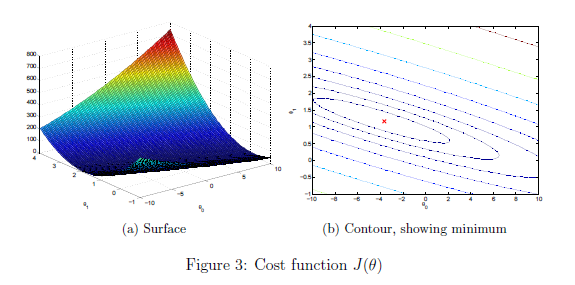

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

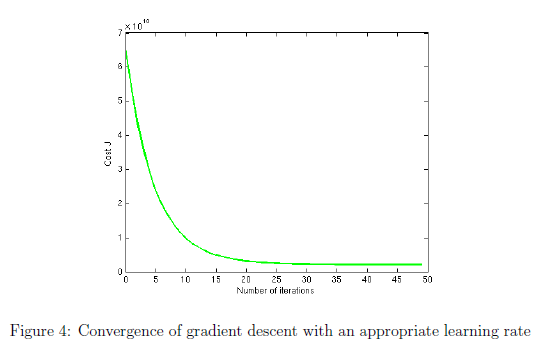

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

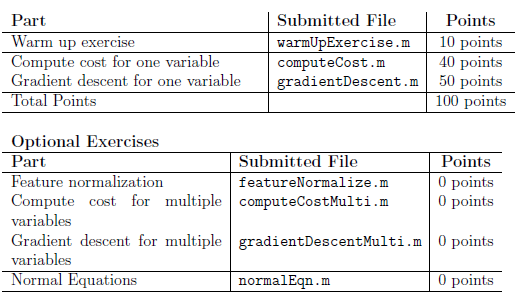

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.